# Note 3

The purpose of this note is to introduce a non-overlapping DDM for the simple 1D nonlinear PDE. 

## Non-overlapping Domain Decomposition

Let us consider again the problem $P$ which asks us to find the solution $u$ given the Dirichlet data $g$.


$$P\left(u;g\right)=\left\lbrace \begin{array}{ll}
F\left(u\left(x\right)\right)=0 & x\in \Omega \;\\
u\left(x\right)=g & x\in \Gamma :=\partial \;\Omega \;
\end{array}\right.$$


In non-overlapping DDM (NDDM), you divide the domain $\Omega$ into domains such that the subdomains $\Omega_i$ 

- the subdomains cover the entire domain $\Omega$

- the intersection of domains is an empty set

In this decomposition, we naturally form symmetric artificial interfaces $\Gamma_{\textrm{ij}} =\bar{\Omega_i } \cap \bar{\Omega_j }$. Unlike the ODDM, we do not impose Dirichlet conditions on the interface. Instead we use Robin conditions. If we assume that the original solution is $C^2$ then on any interface $\Gamma_{\textrm{ij}}$ we must have the continuity conditions: 


$$\left\lbrace \begin{array}{l}
u_i =u_j \\
\partial_i u_i ={-\partial }_j u_j 
\end{array}\right.$$


where the derivative $\partial_i =\nabla \cdot \overrightarrow{n_i }$ defined on $\partial \Omega_i$ is the normal derivative pointing outward from domain $\Omega_i$. The continuity condition can be rewritten as the following:


$$\left\lbrace \begin{array}{l}
\beta u_i +\partial_i u_i =\beta u_j -\partial_j u_j \\
\beta u_j +\partial_j u_j =\beta u_i -\partial_i u_i 
\end{array}\right.$$


where the $\beta \not= 0$ is some constant. This is called the transmission condition. Now we can define the local problem

$P_i \left(u_i ;g,g_{\textrm{ij}} \right)=\left\lbrace \begin{array}{ll}
F_i \left(u_i \left(x\right)\right)=0 & x\in \Omega_i \\
u_i \left(x\right)=g & x\in \Gamma_i \\
\beta u_i \left(x\right)+\partial_i u_i \left(x\right)=g_{\textrm{ij}}  & x\in \Gamma_{\textrm{ij}} ,\forall \;j
\end{array}\right.$.

## Algorithm 

The Robin condition NDDM proceeds is the almost the same as the Schwarz algorithm

- Solve $P_i \left(u_i^{\left(0\right)} ,g,0\right)$$,\forall \;i\;$

- Let $g_{\textrm{ij}}^{\left(n+1\right)} =\beta {{u_j }^{\left(n\right)} } -\partial_j {{u_j }^{\left(n\right)} }$

- For $n=1\;\textrm{to}\;n_{\max }$, 

-     solve $P_i \left(u_i^{\left(n\right)} ,g,{g_{\textrm{ij}} }^{\left(n-1\right)} \right)$$,\forall \;i\;$

There is a way to make the update step more more efficient. The new Robin data can be computed with


$$g_{\textrm{ij}}^{\left(n+1\right)} =-g_{\textrm{ji}}^{\left(n\right)} +2\beta \;u_i^{\left(n\right)}$$
 

so the derivative doesn't need to computed each time. 

## 1-D Case

Suppose decompose the interval $\left(a,b\right)$ with $N_{\textrm{dom}}$ subdomains. In 1D, we only need to select $N_{\textrm{dom}} -1$ interface points to seperate the domains. The $i$th interface point seperates domains $\Omega_i$ and $\Omega_{i+1}$. The location of the interface nodes need not be uniformly distributed.  

In 1-D you don't describe continuity with directional derivatives. Thus the transmission equations are different:  


$$\left\lbrace \begin{array}{l}
u_i =u_j \\
\dot{u_i } =\dot{{\;u}_j } 
\end{array}\Rightarrow \left\lbrace \begin{array}{l}
\beta u_i +u_i =\beta u_j +{\;u}_j \\
\beta u_i -u_i =\beta u_j -{\;u}_j 
\end{array}\right.\right.$$


Unlike in higher dimensions, you do not have the same boundary condition all around the surface. You will have summation Robin on one end and a differcence Robin on the other. 

## Discretization 

The discretization of the PDE will be the same as discussed in Note 1. There are derivative terms in the Robin condition will be discretized with forward or backward difference depending on the sign. For the Monge-Ampere, we need a monotonic difference scheme. Thus, the sign on the derivative term is significant. We must enforce the summation Robin to the right end and the difference Robin to the left end. The local problem on $\Omega_i$ where $i$ is not the 1 nor $N_{\textrm{dom}}$ is given by 


$$P_i \left(u_i ;g_{i,i-1} ,g_{i,i+1} \right)=\left\lbrace \begin{array}{ll}
F_i \left(u_i \left(x\right)\right)=0 & x\in \Omega_i \\
\beta u_i -\dot{u_i } =g_{i,i-1}  & \textrm{on}\;\Gamma_{i,i-1} \;\\
\beta u_i +\dot{u_i } =g_{i,i+1}  & \textrm{on}\;\Gamma_{i,i+1} 
\end{array}\right.$$


If $\Omega_i$ lies on either far end of the domain, then we use the Dirichlet condition instead. 

We use the scheme


$$\beta u_i \left(x\right)-\dot{u_i } \left(x\right)\approx \beta \;u_i \left(x\right)-\frac{u\left(x+h\right)-u\left(x\right)}{h}$$


for the left end and 


$$\beta u_i \left(x\right)+\dot{u_i } \left(x\right)\approx \;$$

$$\beta \;u_i \left(x\right)+\frac{u\left(x\right)-u\left(x-h\right)}{h}$$


for the right end to ensue monotonicity. 

## 1-D Mesh 

In the DDM, only the Dirichlet trace and the previous Robin data is transferred. This is different from the ODDM because you do not need to send a solution on the interior node. What this means is that in 1D, each sub-domain can have a different meshsize with no extra complication to the data sharing process. 

To generate a mesh, you select $N_{\textrm{dom}} -1$ interface points over the inteval $\left(a,b\right)$. Then for each sub-domain, you select a step size $h_i$. 

The following is an example of a 1D mesh of the intreval (0,1). 

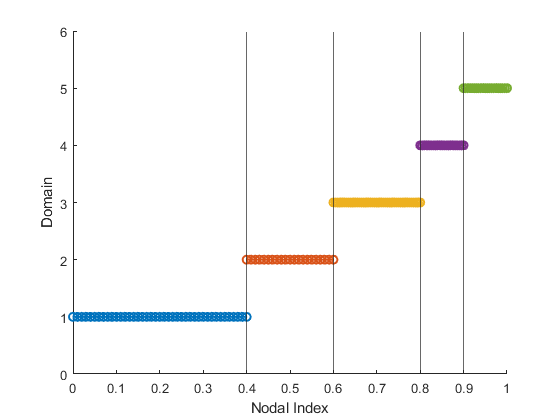

% domain (0,1)
a = 0;
b = 1;

num_dom = 5;
int = [.4 .6 .8 .9];
step_sizes = [100 100 200 200 200].^(-1);

x_i = cell(num_dom,1); % mesh of subdomain
u_i = cell(num_dom,1); % cell of solutions from each dom

for i = 1:num_dom
    if (i==1)
        x_i{i} = a:step_sizes(i):int(1);
    elseif(i==num_dom)
        x_i{i} = int(num_dom-1):step_sizes(i):b;
    else
        x_i{i} = int(i-1):step_sizes(i):int(i);
    end
    u_i{i} = x_i{i}*0; % just initializing the solution 
end

figure
hold on
for i = 1:num_dom
    n = length(x_i{i});
    plot(x_i{i}, i*ones(n,1),'o-','LineWidth',1.5)
end

for i = 1:num_dom-1
    xline(int(i))
end
ylim([0, num_dom+1])
yticks(0:num_dom+1)
xlabel('Nodal Index')
ylabel('Domain')

## DDM Implementation

We, again, use the fsolve subroutine to solve a non-linear discrete system. The discretization of the local problem is given in the function `D`. In addition to the 2 data points, it also needs to know the index of the subdomain with respect to the total number of subdomains. 

Information needed:

- Location of the interface nodes

- Mesh size for each sub-domain

- We need to record the solution computed at each subdomain

- We need to keep track of the data ${g_{\textrm{ij}} }^{\left(n\right)}$ 

- For a while loop, we need to keep track of the residue

max_itr = 300;
g_data = zeros(num_dom,2,max_itr+1); % left & right dirichlet data for each dom, and for each iteration

For the Dirichlet data, we will continue to use 0 and 1. 

ga = 0;
gb = 1;
g_data(1,1,:) = ga;  % left data of domain 1
g_data(end,2,:) = gb; % right data of last domain


This is the actual iteration. In each iteration, 

- Solve the local problems on each sub-domain

- Compute the next set of boundary data

beta = 11;
opt = optimoptions('fsolve','Display','off'); % options for fsolve
for n = 1:max_itr % DDM Iteration
  
    % 1. solve local probs
    for i = 1:num_dom
                           % D(u,c1,c2,h,index,num_dom,beta)
        u_i{i} = fsolve(@(u) D(u,g_data(i,1,n),g_data(i,2,n),step_sizes(i),i,num_dom,beta),u_i{i},opt);
    end
    
    % 2. compute g_new = -g_old + 2*beta*u 
    g_data(1,2,n+1) = -g_data(2,1,n) + 2*beta*u_i{2}(1);
    
    for i = 2:num_dom-1
        g_data(i,1,n+1) = -g_data(i-1,2,n) + 2*beta*u_i{i-1}(end); % Left BD from previous domain
        g_data(i,2,n+1) = -g_data(i+1,1,n) + 2*beta*u_i{i+1}(1); % Right BD from next domain
    end
    
    g_data(end,1,n+1) = -g_data(end-1,2,n) + 2*beta*u_i{end-1}(end); % left BD for last domain
  
end

## Visualizing 

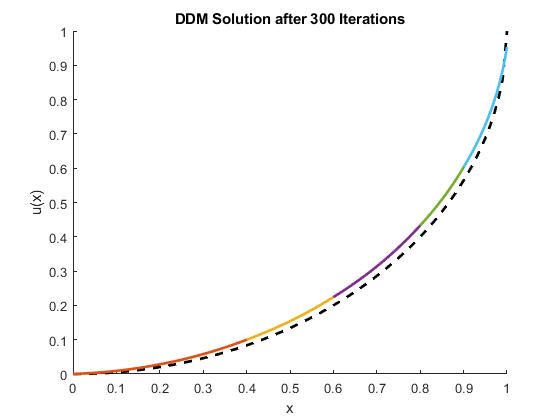

xx = linspace(a,b);
u_exact =@(x) -sqrt(1-x.^2)+1; % exact viscosity solution 

figure, hold on
plot(xx,u_exact(xx),'k--','LineWidth',2)
for i = 1:num_dom
    plot(x_i{i},u_i{i},'LineWidth',2) % plot each subdomain solution
end
title(sprintf('DDM Solution after %d Iterations',max_itr))
xlabel('x'), ylabel('u(x)')

function F = D(u,c1,c2,h,index,num_dom,beta)
N = length(u);
F = zeros(N,1);
ih2 = 1/h^2;

% 1st node
if (index==1) % first domain 
    F(1) = ih2*(u(2)-2*u(1)+c1)-(1+ih2*max([u(1)-c1,u(1)-u(2),0])^2)^(3/2);
else % middle or last domain
    F(1) = beta*u(1) + (u(1)-u(2))/h - c1;
end

% middle nodes
for j = 2:N-1
    F(j) = ih2*(u(j+1)-2*u(j)+u(j-1))-(1+ih2*max([u(j)-u(j-1),u(j)-u(j+1),0])^2)^(3/2);
end

% final node 
if (index==num_dom) % last domain 
    F(N) = ih2*(c2-2*u(N)+u(N-1))-(1+ih2*max([u(N)-u(N-1),u(N)-c2,0])^2)^(3/2);
else % first or middle domain
    F(N) = beta*u(N) + (u(N)-u(N-1))/h - c2;
end

end